% // Ali Yasar 26021 //
% This code iterates a degree of freedom to approxiamte a exact solution with using a weighted residual method
% For that code shape functions considered as Ni = sin(i*pi*x/2/L) and Ni=1-cos(i*pi*x/4/L)

clear all ; 
clc;

syms x k xsi

Area = pi*10^-4; %m^2
L = 1; %m
E = 120*10^9; %Pa
p = 2700; %kg/m^3
Fmax = 50;%N/m
g = 9.81; %m/s^2
f = g*p;
Ero = 1*10^-3;
error = 1;


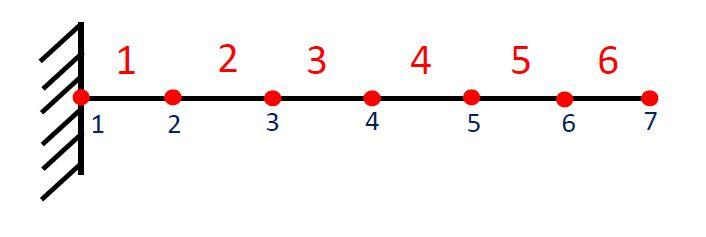


for i = 1:10
number_of_elements = 1;
number_of_nodesperelements = 2; 
totalnumber_of_nodes = number_of_elements + 1; 
ha = L/number_of_elements ; %under the uniform mesh assumption
%Exact solution
u_exact(x)=((Fmax*(x^3))/E/Area/L/6)+((((-f)/E/2) - (Fmax/E/Area/2))*(x^2))+((f*L/E)+(Fmax*L/2/E/Area))*x;
errorDenum = double(sqrt(int(u_exact^2,[0,L])));
K_m = [1,-1;-1,1];
XSI_m = [-1,1];
%--------------BuildsIEN-----------------%


% a,b = number_of_nodesperelements;
for e = 1:number_of_elements 
    for a = 1:number_of_nodesperelements
        IEN(a,e) = (a+e)-1;
    end
end

for o = 1:totalnumber_of_nodes
  ID(o) = o-1; %the condition that g(0)=0
  X(o) = ha*(o-1); 
end


K = zeros(number_of_elements,number_of_elements);
F_Global = zeros(number_of_elements,1); 

for Elem = 1:number_of_elements
    for A = 1: number_of_nodesperelements
        for B = 1:number_of_nodesperelements
            k(A,B) = double(((E*Area/(X(Elem+1)-X(Elem))*K_m(A,B))));
            F(A,1) = double((f*Area*X(Elem+1)-X(Elem))/2);
            I = ID(IEN(A,Elem));
            J = ID(IEN(B,Elem));
            if I ~= 0 && J ~= 0
                K(I,J) = K(I,J)+k(A,B);
                F_Global(I,1) = F_Global(I,1)+F(A,1);
%             else
                %You need to add a g term there
            end
        end
    end
end
D = K\F_Global;

ActualD = zeros(number_of_elements+1,1);
for p = 1:number_of_elements
    ActualD(p+1,1) = ActualD(p+1,1) + D(p,1);
end
ActualD;

%----------Building Uh-----------%

Uh = 0;
errorNum = 0;
for p = 1:number_of_elements
       Xsi(x) = (2*x-X(p)-X(p+1))/(X(p+1)-X(p));
       Uh = 0.5*(1+XSI_m(1)*(Xsi(x)))*ActualD(p,1)+0.5*(1+XSI_m(2)*(Xsi(x)))*ActualD(p+1,1); 
       u_exact(x)=((Fmax*(x^3))/E/Area/L/6)+((((-f)/E/2) - (Fmax/E/Area/2))*(x^2))+((f*L/E)+(Fmax*L/2/E/Area))*x;
       integral(p,1) = double(int(Uh^2 + u_exact^2 - 2*Uh*u_exact,X(p),X(p+1)));
       errorNum =  errorNum + integral(p,1);
end
    
Error(i) = double(sqrt(errorNum))/double(sqrt(errorDenum));
number_of_elements = number_of_elements + 1;
end

Error

Error = 1.0e-03 *

   0.385690359384902   0.385690359384902   0.385690359384902   0.385690359384902   0.385690359384902   0.385690359384902   0.385690359384902   0.385690359384902   0.385690359384902   0.385690359384902
